# Generating cost

## Import the data

### Import DAM LBMP data in 2019

clear;
% Import hourly DAM LBMP data in Jan 2019
priceFileDir = "D:\EERL\ny_academic_model\data\2019_DAM_LBMP_Generator\";
priceFileName = '2019*damlbmp_gen.csv';
DAMPriceDataShoreJan = fileDatastore(priceFileDir + priceFileName, "ReadFcn", @importDAMPriceData, "UniformRead", true);
priceAll = readall(DAMPriceDataShoreJan);
clear DAMPriceDataShoreJan;

% Format datetime to match the generation dataset
priceAll.Date = dateshift(priceAll.TimeStamp, 'start', 'day');
priceAll.Hour = priceAll.TimeStamp.Hour

priceAll = 4877764×8 table
       TimeStamp             NYISOname           PTID     LBMPMWHr    MarginalCostLossesMWHr    MarginalCostCongestionMWHr          Date          Hour
    ________________    ____________________    ______    ________    ______________________    __________________________    ________________    ____

    01/01/2019 00:00    59TH STREET_GT_1        24138      25.73               0.99                        -14.4              01/01/2019 00:00     0  
    01/01/2019 00:00    74TH STREET_GT_1        24260      25.48               1.01                       -14.12              01/01/2019 00:00     0  
    01/01/2019 00:00    74TH STREET_GT_2        24261      25.48               1.01             

### Import generation data in 2019

genFileDir = "D:\EERL\ny_academic_model\data\EPA_AMPD\2019\";
genFileName = "emission*.csv";
generationDataStore = fileDatastore(genFileDir + genFileName, "ReadFcn", @importGenerationData, "UniformRead", true);
genAll = readall(generationDataStore);
clear generationDataStore

### Import RGGI to NYCA reference table

% Import the reference table from RGGI to NYISO NYCA database
RGGI2NYCA2019 = importRGGI2NYCA("D:\EERL\ny_academic_model\data\EPA_AMPD\RGGI_2_NYCA_2019.xlsx");
generatorCombiner = RGGI2NYCA2019(:, ["NYISOname", "PTID", "FacilityName", "FacilityID", "UnitID", "NYAMUnit", "Region", "UnitType", "FuelType", "NamePlateRatingMW"]);
% Exclude generators that are not included in NYAM units
generatorCombiner = generatorCombiner(generatorCombiner.NYAMUnit ~= 'NA',:);
% Exclude generators fueling on wood and refuse (renewable energy)
generatorCombiner = generatorCombiner(generatorCombiner.FuelType ~= "Wood" & generatorCombiner.FuelType ~= "Refuse", :);
% Remove unused categories
generatorCombiner.NYISOname = removecats(generatorCombiner.NYISOname);
generatorCombiner.PTID = removecats(generatorCombiner.PTID);
generatorCombiner.FacilityName = removecats(generatorCombiner.FacilityName);
generatorCombiner.FacilityID = removecats(generatorCombiner.FacilityID);
generatorCombiner.UnitID = removecats(generatorCombiner.UnitID);
generatorCombiner.NYAMUnit = removecats(generatorCombiner.NYAMUnit);
generatorCombiner.Region = removecats(generatorCombiner.Region);
generatorCombiner.UnitType = removecats(generatorCombiner.UnitType);
generatorCombiner.FuelType = removecats(generatorCombiner.FuelType);

## Combine data tables

### Combine the generation data with the reference table

% Join tables generation data with the reference table
jiontGenAll = outerjoin(genAll,generatorCombiner,'Type', 'right', 'Keys',{'FacilityName','FacilityID','UnitID'},...
    "LeftVariables", {'Date', 'Hour', 'GrossLoadMW', 'OperatingTime', 'HeatInputMMBtu'}, "RightVariables", ...
    {'NYISOname', 'PTID', 'FacilityName', 'FacilityID', 'NYAMUnit', 'Region', 'UnitType', 'FuelType', 'NamePlateRatingMW'})

jiontGenAll = 1454160×14 table
       Date       Hour    GrossLoadMW    OperatingTime    HeatInputMMBtu    NYISOname    PTID     FacilityName    FacilityID    NYAMUnit    Region         UnitType          FuelType      NamePlateRatingMW
    __________    ____    ___________    _____________    ______________    _________    _____    ____________    __________    ________    ______    __________________    ___________    _________________

    01/01/2019      0          0               0                0           Gowanu

### Combine the joint generation data with price data

% Join tables
GenPriceAll = outerjoin(jiontGenAll,priceAll,'Type','left','Keys',{'Date','Hour','PTID'},'MergeKeys',true, ...
    "LeftVariables", {'Date', 'Hour', 'NYISOname', 'PTID', 'NYAMUnit', 'Region', 'UnitType', 'FuelType', 'GrossLoadMW', 'HeatInputMMBtu', 'NamePlateRatingMW', 'OperatingTime'}, ...
    "RightVariables", {'LBMPMWHr', 'MarginalCostCongestionMWHr', 'MarginalCostLossesMWHr'})

GenPriceAll = 1454318×15 table
       Date       Hour        NYISOname         PTID     NYAMUnit    Region         UnitType          FuelType      GrossLoadMW    HeatInputMMBtu    NamePlateRatingMW    OperatingTime    LBMPMWHr    MarginalCostCongestionMWHr    MarginalCostLossesMWHr
    __________    ____    __________________    _____    ________    ______    __________________    ___________    ___________    ______________    _________________    _____________    ________    __________________________

## Subset the data

### subset data table with NYAM units

% Subset the generator summary table by NYAM units
GenPriceA2FCC = GenPriceAll(GenPriceAll.NYAMUnit == "A2F-CC", :);
GenPriceA2FST = GenPriceAll(GenPriceAll.NYAMUnit == "A2F-ST", :);
GenPriceGHIST = GenPriceAll(GenPriceAll.NYAMUnit == "GHI-ST", :);
GenPriceJCC = GenPriceAll(GenPriceAll.NYAMUnit == "J-CC", :);
GenPriceJCT = GenPriceAll(GenPriceAll.NYAMUnit == "J-CT", :);
GenPriceJST = GenPriceAll(GenPriceAll.NYAMUnit == "J-ST", :);
GenPriceKCT = GenPriceAll(GenPriceAll.NYAMUnit == "K-CT", :);
GenPriceKST = GenPriceAll(GenPriceAll.NYAMUnit == "K-ST", :);

GenPriceA2FCC

GenPriceA2FCC = 324149×15 table
       Date       Hour          NYISOname          PTID     NYAMUnit    Region       UnitType        FuelType      GrossLoadMW    HeatInputMMBtu    NamePlateRatingMW    OperatingTime    LBMPMWHr    MarginalCostCongestionMWHr    MarginalCostLossesMWHr
    __________    ____    _____________________    _____    ________    ______    ______________    ___________    ___________    ______________    _________________    _____________    ________    __________________________

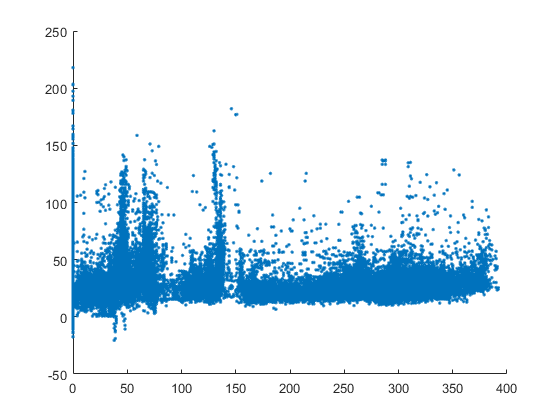

scatter(GenPriceA2FCC.GrossLoadMW, GenPriceA2FCC.LBMPMWHr, ".")

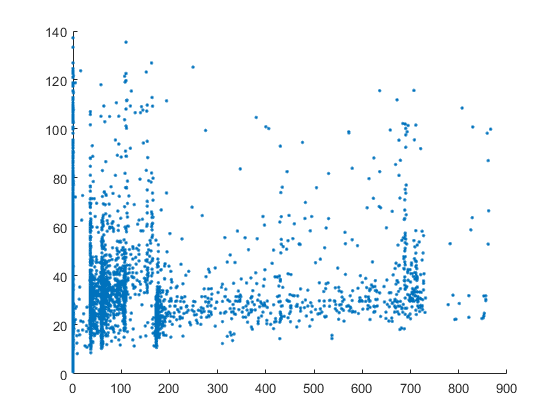

scatter(GenPriceA2FST.GrossLoadMW, GenPriceA2FST.LBMPMWHr, ".")

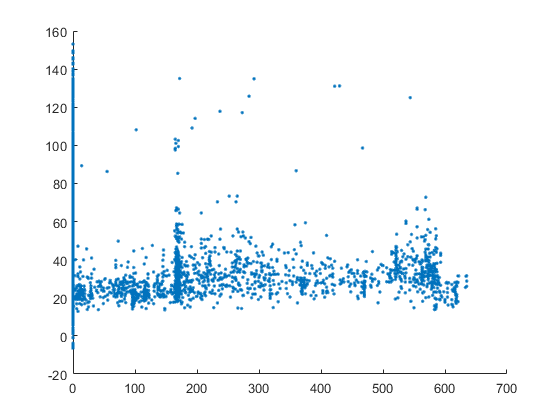

scatter(GenPriceGHIST.GrossLoadMW, GenPriceGHIST.LBMPMWHr, ".")

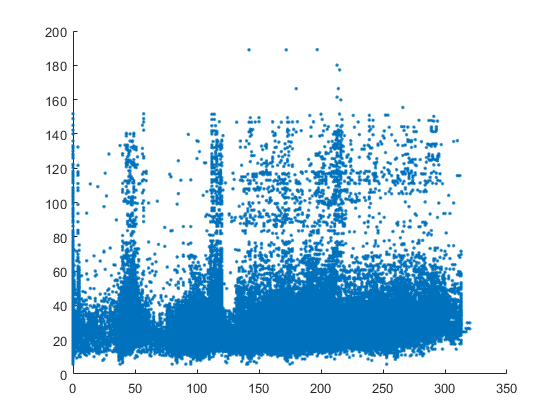

scatter(GenPriceJCC.GrossLoadMW, GenPriceJCC.LBMPMWHr, ".")

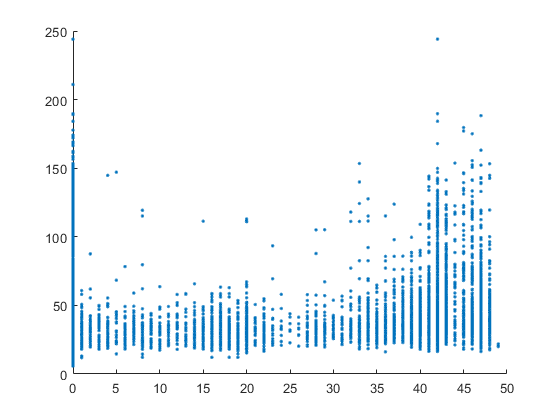

scatter(GenPriceJCT.GrossLoadMW, GenPriceJCT.LBMPMWHr, ".")

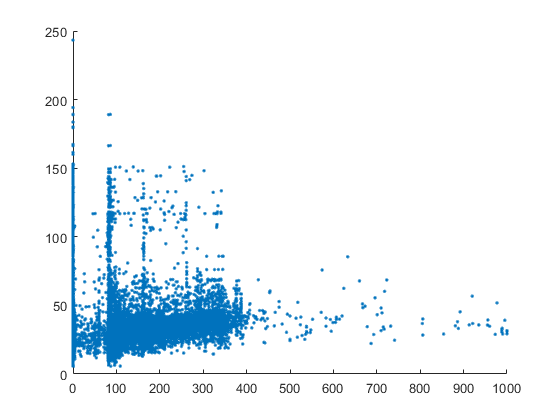

scatter(GenPriceJST.GrossLoadMW, GenPriceJST.LBMPMWHr, ".")

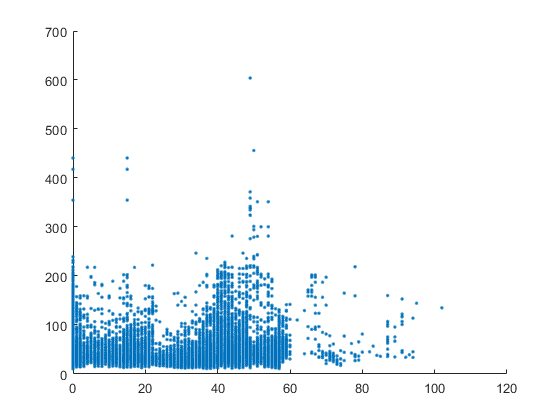

scatter(GenPriceKCT.GrossLoadMW, GenPriceKCT.LBMPMWHr, ".")

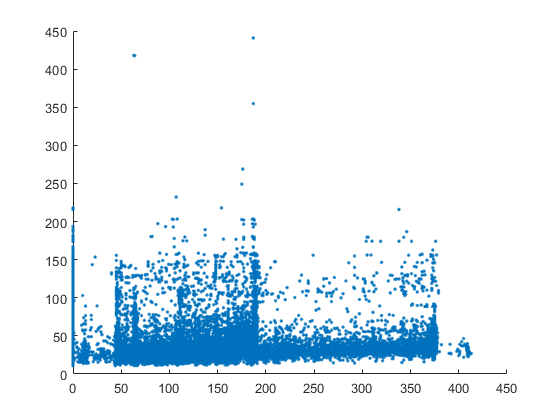

scatter(GenPriceKST.GrossLoadMW, GenPriceKST.LBMPMWHr, ".")